# **Lung CT image segmentation**

A CT scan of 136 images in 10 times instances was given. The patient is 67-year-old.

Images were firstly extracted for all time instances. Moreover, since DICOM files were analysed, `info` were taken from the first image to obtain the features of the slices.

T = [{'0'}, {'10'}, {'20'}, {'30'}, {'40'},{'50'}, {'60'}, {'70'}, {'80'}, {'90'}];
vol = cell(length(T), 1);

for ti = 1:length(T)
    [vol{ti}, ~] = readDCMfolder(T{ti});
end
folder = ['Patient0/T_', '0', '/CT/'];
D = dir([folder, '*.dcm']);
info = dicominfo([folder, D(1).name]);

First slice at time 0 was considered to properly choose the adjustement parameter gamma. Image was firstly normalised. Thank to `imcrop `function, a ROI (Region of Interest) was chosen and kept for all the other slices. The aim was to isolate lungs only. *ROI is saved in variable RECT.mat*.

t=1;
im = vol{t}(:,:,1);

%Normalisation
max_im = max(im(:));
min_im = min(im(:));
im = (im-min_im)./(max_im-min_im);
figure
[im, RECT_xy] = imcrop(im);
%load("ROI.mat")
%im = imcrop(im, RECT)
gamma_vect = 0.2:0.2:1.2;
LOW_IN = min(im(:));
HIGH_IN = max(im(:));
LOW_OUT = 0;
HIGH_OUT = 1;
im_adj= zeros(size(im,1),size(im,2),length(gamma_vect));
for i = 1:length(gamma_vect)
    im_adj(:,:,i) = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(i));
end

figure
montage(im_adj)
title(strcat('gamma = ', num2str(gamma_vect)))

Gamma was chosen to be 0.6 because image with this adjustment is able to better enhance lungs with details in respect to the background. `getps `function was used to manually select pixels belonging to the lungs, in order to create a mask to then perform segmentation.

im_adj = imadjust(im, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(3));
figure, imshow(im_adj, [], 'InitialMagnification', 'fit')
[X_xy,Y_xy] = getpts();

Histogram of the adjusted image was plotted to choose the right threshold (0.5) for T-transformation:


$$\left\lbrace \begin{array}{ll}
\textrm{im}>0\ldotp 5 & 0\\
\textrm{im}<0\ldotp 5 & \textrm{keep}
\end{array}\right.$$


figure, imhist(im_adj)

### **All time instants **

Slices of interest were the ones containing lungs. Therefore, only the first 59 slices were taken into consideration.

Each slice was segmented by performing the normalisation, the adjustment and the conversion into binary (with `bwselect`) to obtain the mask. The image was finally multiplied by the mask.

segmented_image_XY = cell(1,length(T));
gamma = gamma_vect(3);
segmented_image = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 7);

For each segmented slice, cross-sectional area over axial slices was calculated. Since area of lungs is usually different from left to right, they were plotted individually. As it can be seen from the graph below, left lung shows a smaller overall area due to the presence of the heart; the trend is similar.

t=1;
for i = 1:52
    slice = segmented_image{t}(:,:,i);
     AreaLungsPixels = regionprops(logical(slice), 'Area');
        AreaLungsPixels = struct2table(AreaLungsPixels);
        spacingx = 0.976;
        spacingy = 0.976;
        spacingz = 2.5;
        unitar = spacingx*spacingy;
        AreaSx_as(i) = (AreaLungsPixels.Area(2)*unitar)*1e-2;
        AreaDx_as(i) = (AreaLungsPixels.Area(1)*unitar)*1e-2;
end
        figure, plot(1:52, AreaSx_as, 1:52, AreaDx_as)
        legend('Sx', 'Dx')
        title('Area')
        xlabel('Slices [-]')
        ylabel('Cross-sectional area [cm^2]')

Area_tot = cell(length(T), 1);
Area_tot = Area_XY(segmented_image, T);
for t=1:length(T)
    figure, plot(1:52, Area_tot{t});
    title(['Axial slice cross-sectional area ', num2str(t)])
    xlabel('Slices [-]')
    ylabel('Cross-sectional area [cm^2]')
end 

## Coronal - sectional Area (XZ)

im_XZ = squeeze(vol{1}(290,:,:));
%Normalization
max_im = max(im_XZ(:));
min_im = min(im_XZ(:));
im_XZ = (im_XZ-min_im)./(max_im-min_im);
%figure
%[im_XZ, RECT_xz] = imcrop(im_XZ);
gamma_vect = 0.2:0.2:1.2;
LOW_IN = min(im_XZ(:));
HIGH_IN = max(im_XZ(:));
LOW_OUT = 0;
HIGH_OUT = 1;
im_adj_XZ= zeros(size(im_XZ,1),size(im_XZ,2),length(gamma_vect));
for i = 1:length(gamma_vect)
    im_adj_XZ(:,:,i) = imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], gamma_vect(i));
end

figure
montage(im_adj_XZ)
title(strcat('gamma = ', num2str(gamma_vect)))
im_adj_XZ= imadjust(im_XZ, [LOW_IN HIGH_IN], [LOW_OUT HIGH_OUT], 1.2);
figure, imshow(im_adj_XZ, [], 'InitialMagnification', 'fit')
[X_xz,Z_xz] = getpts();

figure, imhist(im_adj_XZ)

gamma = 1.2;
segmented_image_XZ = cell(1,length(T));
segmented_image_XZ = Segment_XZ(vol, T, gamma, X_xz, Z_xz);

t = 1;
for i = 1:135
    slice_XZ = segmented_image_XZ{t}(i,:,:);
    AreaLungsPixels_XZ = regionprops(logical(slice_XZ), 'Area');
    AreaLungsPixels_XZ = struct2table(AreaLungsPixels_XZ);
    spacingx = 0.976;
    spacingy = 0.976;
    spacingz = 2.5;
    unitar_XZ = spacingx*spacingz;
    %AreaLungsPixels_XZ_sum=sum(AreaLungsPixels_XZ.Area);
    %Area_tot_XZ(i)=(AreaLungsPixels_XZ_sum*unitar_XZ)*1e-2;
    AreaSx_cs(i) = (AreaLungsPixels_XZ.Area(1)*unitar_XZ)*1e-2;
    AreaDx_cs(i) = (AreaLungsPixels_XZ.Area(2)*unitar_XZ)*1e-2;
end

figure, plot(1:135, AreaSx_cs, 1:135, AreaDx_cs)
title('Area')
xlabel('Slices [-]')
ylabel('Cross-sectional area [cm^2]')
for t = 1:length(T)
    for i = 1:135
    slice_XZ = segmented_image_XZ{t}(i,:,:);
    AreaLungsPixels_XZ = regionprops(logical(slice_XZ), 'Area');
    AreaLungsPixels_XZ = struct2table(AreaLungsPixels_XZ);
    spacingx = 0.976;
    spacingy = 0.976;
    spacingz = 2.5;
    unitar_XZ = spacingx*spacingz;
    Area_tot_XZ{t}(i)=(sum(AreaLungsPixels_XZ.Area)*unitar_XZ)*1e-2;
    end
    figure, plot(1:135, Area_tot_XZ{t})
    title('Area')
    xlabel('Slices [-]')
    ylabel('Cross-sectional area [cm^2]')
end

## Volume at t=0

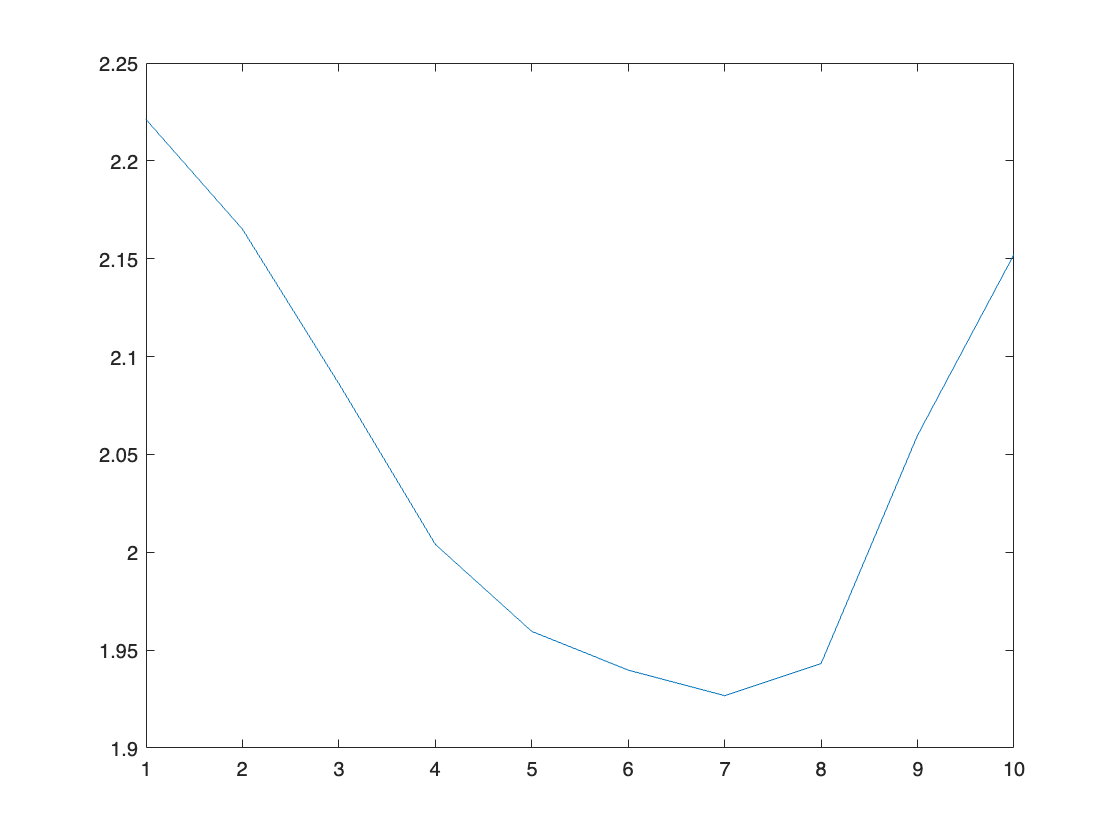

volLungs = zeros(length(T), 1);

volLungs = Volume(segmented_image,T);

figure
plot(1:10, volLungs)

### Noise

Noise is tested on axial slices.

gamma = 0.6;
segmented_image_gaussian1 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 1);
segmented_image_gaussian2 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 2);
segmented_image_gaussian3 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 3);
segmented_image_sp1 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 4);
segmented_image_sp2 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 5);
segmented_image_sp3 = Segment_XY(vol, T, gamma, RECT_xy, X_xy, Y_xy, 6);

figure
imshow(segmented_image{1}(:,:,1), [], 'InitialMagnification', 'fit')

figure 
subplot(421), imshow(segmented_image_gaussian1{1}(:,:,1), [])
subplot(422), imshow(segmented_image_gaussian2{1}(:,:,1), [])
subplot(423), imshow(segmented_image_gaussian3{1}(:,:,1), [])
subplot(424), imshow(segmented_image_sp1{1}(:,:,1), [])
subplot(425), imshow(segmented_image_sp2{1}(:,:,1), [])
subplot(426), imshow(segmented_image_sp3{1}(:,:,1), [])

Segmentation with low values of gaussian noise seemed to work well, while with higher values segmentations was poorly performed. On the other hand, salt & pepper noise with values chosen seems not to disturb segmentation.

Area was calculated just for well segmented images.

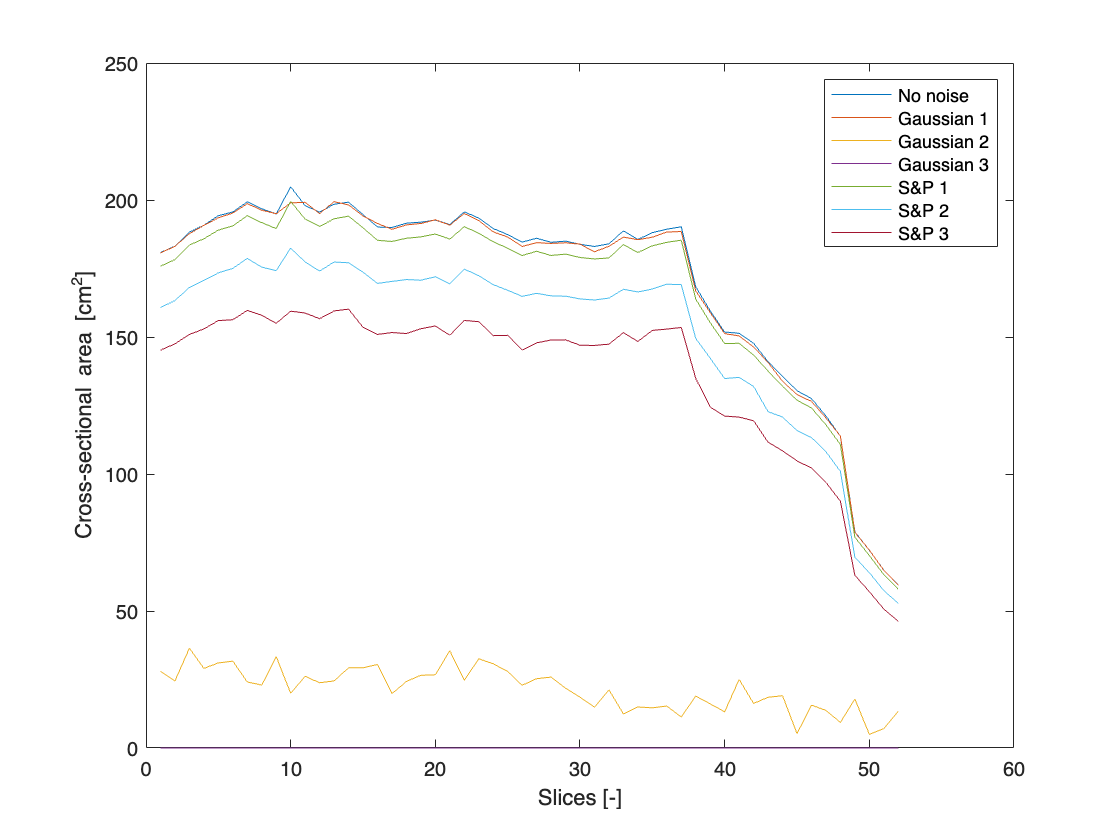

Area_totG1 = cell(length(T), 1);
Area_totSP1 = cell(length(T), 1);
Area_totSP2 = cell(length(T), 1);
Area_totSP3 = cell(length(T), 1);
Area_totG1 = Area_XY(segmented_image_gaussian1, T);
Area_totG2 = Area_XY(segmented_image_gaussian2, T);
Area_totG3 = Area_XY(segmented_image_gaussian3, T);
Area_totSP1 = Area_XY(segmented_image_sp1, T);
Area_totSP2 = Area_XY(segmented_image_sp2, T);
Area_totSP3 = Area_XY(segmented_image_sp3, T);
figure
plot(1:52, Area_tot{1});
hold on
plot(1:52, Area_totG1{1});
plot(1:52, Area_totG2{1});
plot(1:52, Area_totG3{1});
plot(1:52, Area_totSP1{1});
plot(1:52, Area_totSP2{1});
plot(1:52, Area_totSP3{1});
legend('No noise','Gaussian 1', 'Gaussian 2', 'Gaussian 3', 'S&P 1', 'S&P 2', 'S&P 3')
    xlabel('Slices [-]')
    ylabel('Cross-sectional area [cm^2]')

Volume

volLungsG1 = zeros(length(T), 1);
volLungsG1 = Volume(segmented_image_gaussian1,T);
volLungsG2 = zeros(length(T), 1);
volLungsG2 = Volume(segmented_image_gaussian2,T);
volLungsSP1 = zeros(length(T), 1);
volLungsSP1 = Volume(segmented_image_sp1,T);
volLungsSP2 = zeros(length(T), 1);
volLungsSP2 = Volume(segmented_image_sp2,T);
volLungsSP3 = zeros(length(T), 1);
volLungsSP3 = Volume(segmented_image_sp3,T);

figure
plot(1:10, volLungs)
hold on
plot(1:10, volLungsG1)
plot(1:10, volLungsG2)
plot(1:10, volLungsSP1)
plot(1:10, volLungsSP2)
plot(1:10, volLungsSP3)
legend('No noise','Gaussian 1', 'Gaussian 2', 'S&P 1', 'S&P 2', 'S&P 3')
xlabel('Time')
ylabel('Volume [cm^3]')